# การสร้างและใช้งาน "เมตริกซ์" ในโปรแกรม MATLAB

โดย อาจารย์ ธนัชชา ชูพจน์เจริญ

# Using "Matrix" in MATLAB

Author :  Thanacha Choopojcharoen

Copyright : Thanacha Choopojcharoen

## จุดประสงค์

เอกสารนี้จัดทำขึ้นเพื่ออธิบายถึงการใช้งานขั้นพื้นฐานของโปรแกม MATLAB ซึ่งผู้เรียนสามารถ

- ระบุและกำหนดมิติของ tensor

- สร้าง เลือกหรือลบสมาชิกของเวกเตอร์ และคำนวณโดยใช้เวกเตอร์

- สร้าง เลือกหรือลบสมาชิกของเมตริกซ์ และคำนวณโดยใช้เมตริกซ์

## 1) มิติของ Tensor ใน MATLAB

MATLAB มาจากคำว่า Matrix Laboratory ซึ่งมีปรัชญาการทำงานโดยใช้วัตถุทางคณิตศาสตร์ที่เรียกว่า "เมตริกซ์" ทุกแปรใน MATLABจะถูกกำหนดให้เป็นเมตริกซ์ ยกตัวอย่างเช่นค่า scalar จะถูกจัดให้เป็นเมตริกซ์ขนาด 1x1 ด้วย

จากฟังก์ชัน size เราจะสังเกตได้ว่า ตัวแปร a ที่เป็นค่าเป็น scalar นั้น ที่จริงแล้วถูกจัดให้อยู่ในรูปเมตริกซ์ที่มีขนาด 1 แถว และ 1 หลัก ในความเป็นจริงแล้ว การจัดเก็บตัวแปรนั้นไม่ได้ถูกทำในรูปแบบของเมตริกซ์แต่เป็นการจัดเก็บในรูปแบบของ tensor (เนื่องจากเมตริกซ์ใช้อธิบายวัตถุทางคณิตศาสตร์ที่เป็นในรูปแบบของตาราง 2 มิติ แต่ tensor นั้นใช้อธิบายได้ในหลายมิติ)ในภาษาโปรแกรมอื่นๆ วัตถุนี้ถูกเรียกว่า Array ซึ่งสามารถมีได้หลายมิติ  เรื่องของมิติอาจจะดูซับซ้อน ดังนั้นเราต้องเข้าใจการอ้างอิงมิติในโปรแกรม MATLAB 

เนื่องจากว่าเราสามารถให้ tensor เป็นกี่มิติก็ได้ การจะเรียกแต่ละมิติว่า "แถว" "หลัก" หรือ "ความลึก" อาจไม่ใช่วิธีที่ดีที่สุด MATLABจึงใช้ระบบตัวเลขในการอ้างอิงถึงมิติของ tensor เช่น

1 : มิติในแนวแถว

2 : มิติในแนวหลัก

3 : มิติในแนวลึก

แน่นอนว่าเราสามารถสร้าง tensor ที่มี 4 มิติได้หรือมากกว่านั้นได้ นั่นก็หมายความว่า เราสามารถอ้างอิงตามมิตินั้นๆโดยใช้ตัวเลขได้เลย

ตัวอย่างนี้เป็นการสร้าง tensor 4 มิติที่มีขนาด 3x5x4x3 โดยทำการสุ่ม

แต่เพื่อโดยเบื้องต้นแล้ว เราจะใช้ไม่เกิน 3 มิติ

## 2) เวกเตอร์

### 2.1) การสร้างเวกเตอร์

เราจะเรียกArray ที่มี 1 มิติว่า เวกเตอร์หลัก หรือ Column Vector 

 
$$\mathbf{v}=\left\lbrack \begin{array}{c}
{\mathbf{v}}_1 \\
{\mathbf{v}}_2 \\
\cdots \\
{\mathbf{v}}_n 
\end{array}\right\rbrack \in \Re^n$$


Code ตัวอย่างแสดงการสร้างเวกเตอร์โดยใช้ เครื่องหมาย semi-colon (;) ในการขึ้นแถวใหม่  

เราจะสังเกตได้อีกว่าเราสามารถเขียนเวกเตอร์ให้เป็นเวกเตอร์แถวได้ด้วยโดยใช้การเว้นวรรคระหว่างสมาชิก จากนั้นเราทำการ transpose (') เพื่อให้เวกเตอร์แถวกลายเป็นเวกเตอร์หลัก ทั้งสองวิธีนี้ทำให้ได้ผลลัพธ์เป็นเวกเตอร์เดียวกัน

นอกจากนี้ เราสามารถตรวจสอบจำนวนสมาชิกและขนาดของเวกเตอร์ได้โดยใช้ฟังก์ชัน numel และ size ซึ่งฟังก์ชัน size นั้นจะมีเลข 1 กำกับเพื่อระบุในฟังก์ชันทราบอย่างชัดเจนว่าเราต้องการรู้ขนาดของวัตถุนีในมิติที่ 1 ซึ่งก็คือจำนวนของแถวนั้นเอง

หลายครั้ง เราสามารถใช้เวกเตอร์แทนการเขียนลำดับ (sequence) ได้ ในกรณีเช่นนี้ มันอาจจะไม่เหมาะสมที่จะเรียกลำดับว่าเวกเตอร์ ถ้าให้กล่าวอย่างทางการเลยคือ ลำดับไม่ใช่เวกเตอร์ แต่ลำดับสามารถถูกเขียนอยู่ในรูปของเวกเตอร์ได้ หลายคนเลยมักใช้คำว่า Array มากกว่าคำว่า เวกเตอร์ ตัวอย่างของลำดับได้แก่ ลำดับเลขคณิต (arithmetic sequence) 


$$\mathbf{a}={\left\lbrack \begin{array}{cccc}
{\mathbf{a}}_1  & {\mathbf{a}}_2  & \cdots  & {\mathbf{a}}_n 
\end{array}\right\rbrack }^{\top }$$


โดยที่


$$\begin{array}{l}
{\mathbf{a}}_{k+1} ={\mathbf{a}}_k +1\;\;\forall \;k=1,\cdots ,n\\
{\mathbf{a}}_1 =1
\end{array}$$


เราสามารถใช้ทำได้ดังนี้

เราจะได้ลำดับเพิ่มขึ้นที่ละ 1 ในแต่ละพจน์ ซึ่งพจน์แต่ละอันจะถูกเก็บไว้เป็นสมาชิกของเวกเตอร์ นอกจากนี้เรายังสามารถที่จะเพิ่มในแต่ละพจน์ที่เป็นระยะอื่นๆได้เช่น

เราสังเกตได้ว่าขนาดของ a b และ c นั้นจะไม่เท่ากัน หากเราต้องให้จำนวนพจน์เท่ากัน เราต้องใช้ฟังก์ชัน linspace แทนเพื่อจะจัดลำดับเลขคณิตให้มีระยะห่างเท่าๆกันตามจำนวนของพจน์ที่กำหนด แต่เราจำเป็นต้องทำการคำนวณเล็กน้อย

หากเรารู้ความสัมพันธ์ระหว่าง b กับ a  และ c กับ a เราสามารถเขียนทั้งสองเวกเตอร์ในรูปของ a ได้

เราสังเกตได้ว่า ค่า scalar สามารถนำไปคูณกับเวกเตอร์ได้เลย ผลลัพธ์คือค่า scalar นั้นจะถูกคูณกระจ่ายไปยังแต่ละสมาชิก ส่วนถ้าหากต้องการบวกหรือลบเวกเตอร์ด้วยค่าคงที่ที่เหมือนกันในแต่ละสมาชิด เราสามารถบวกหรือลบได่เลยเช่นกัน โปรแกรมนำค่านั้นไปบวกหรือลบในแต่ละสมาชิก ดังนั้น เราจะเห็นได้ว่าเราไม่จำเป็นต้องสร้างตัวแปรที่มีขนาดเท่ากันมาบวกหรือลบ (วิธีดังกล่าวถูกปรับมาให้ใช้ง่ายเป็นอย่างปัจจุบัน เมื่อก่อน MATLAB ไม่อนุญาตให้ผู้ใช้บวกลบตัวแปรที่มีขนาดแตกต่างกัน) 

### 2.2) การเลือกและกำหนดสมาชิกของเวกเตอร์

หากเรามีเวกเตอร์ เราสามารถที่จะอ่านค่าของสมาชิกในเวกเตอร์ได้โดยใช้วงเล็บ () ตามด้วยดัชนีหรือ index ซึ่งภาษา MATLAB เป็นภาษาที่ใช้ระบบ 1-indexing หมายความว่าค่าแรกของสมาชิกใน tensor จะเริ่มที่ดัชนีที่ 1 (ภาษา C หรือ python จะเริ่มที่ 0) 

index ที่ใช้เรียกนั้นจำเป็นจะต้องเป็นจำนวนเต็มบวกที่ไม่มากไปกว่าจำนวนสมาชิกของเวกเตอร์นั้นๆ นอกจากนี้แล้วเรายังสามารถปรับเปลี่ยนค่าของสมาชิกได้

ถ้าหากเวกเตอร์ขนาดที่ยาวมาก มันอาจจะเป็นการเสียเวลาที่ต้องคอยตรวจว่าเวกเตอร์มีขนาดเท่าไหร่ 

เราสามารถใช้ end ในการระบุ index อื่นๆ ได้อีกด้วย

นอกจากนี้ เราสามารถเปลี่ยนแปลงสมาชิกของเวกเตอร์ได้เช่นกัน

หนึ่งในเวกเตอร์พิเศษคือ เวกเตอร์ว่าง (Empty Vector) ซึ่งเป็นเวกเตอร์ไม่มีสมาชิกใดๆเลย หากเรากำหนดให้สมาชิกของเวกเตอร์ใดๆเป็นเวกเตอร์ว่าง โปรแกรมจะทำการลบสมาชิกนั้นออกจากเวกเตอร์และเลื่อนสมาชิกถัดไปเข้ามาในตำแหน่งที่ถูกลบ ซึ่งจะทำให้ขนาดของเวกเตอร์ลดลงด้วย

นอกจากการลดขนาดเวกเตอร์โดยการลบสมาชิกแล้ว เรายังสามารถเพิ่มขนาดเวกเตอร์โดยการต่อเพิ่มจากตัวสุดท้าย

### 2.3) กระบวนการในการคำนวณเวกเตอร์

เราสามารถใช้งานเวกเตอร์ได้เหมือนกับที่เราเรียนในเรื่องพีชคณิตของเวกเตอร์ เช่นการบวก การคูณ การหา Inner Product การหา Outer Product การหา Norm แต่ถ้าหากเราคำนวณใน Euclidean space เราสามารถหา Cross Product ได้กับแค่เวกเตอร์ 3 มิติเท่านั้น (https://www.jstor.org/stable/2323537)

ฟังก์ชั่นเหล่านี้เรียกว่า vector operation 

### 2.4) กระบวนการในการคำนวณทีละสมาชิก

ที่ผ่านมาเราได้มองเวกเตอร์เป็นเหมือนวัตถุทางคณิตศาสตร์ที่มีสมาชิกเป็นแต่ละ องค์ประกอบ (component) ของเวกเตอร์ทั้งหมด แต่เราก็ยังสามารถมองเวกเตอร์เป็นเหมือน Array ที่กำหนดลำดับของข้อมูลได้เช่นกัน ยกตัวอย่างเช่นสมการดังต่อไปนี้


$$y=\sin \left(t\right)$$


สมการดังกล่าวบ่งบอกถึงความสัมพันธ์ระหว่างตัวแปร $t$ และตัวแปร$y$ หากเรามีข้อมูลของตัวแปร $t$จำนวนหนึ่ง เราจะได้ข้อมูลของตัวแปร $y$ ที่มีจำนวนเท่ากัน

เราสังเกตเห็นได้ว่า ฟังก์ชั่น sin นั้นถูกใช้กับทแต่ละสมาชิกของ $t$ ซึ่งแตกต่างกับ Vector operation ที่คำนวณกับทั้งเวกเตอร์ไม่ใช่ทีละสมาชิก กระบวนการแบบนี้ถูกเรียกว่า element-wise operation ดังนั้นเราต้องคอยตระหนักถึงว่ากระบวนการในการคำนวณนั้นเป็น vector/matrix operation หรือ element-wise operation ยกตัวอย่างเช่น


$$y=t^2$$


หลายครั้ง เราสามารถเติม (.) ก่อนหน้า operation เพื่อทำการคำนวณแบบ element-wise เช่น 

### 2.5) การเขียน char 

นอกจากคณิตศาสตร์ MATLAB ยังรองรับตัวแปรประเภทอื่นๆมากมาย หนึ่งในนั้นคือตัวแปรประเภทตัวอักษร (Character) หรือที่ถูกเรียกว่า char ซึ่งสามารถเขียนได้จากตัวอักษร Unicode (ซึ่งงเป็นไปได้ทั้งหมด 65536 ตัวอักษร)  เราสามารถเขียนค่า char ได้โดยใช้เครื่องหมาย ' ' 

## 3) เมตริกซ์

### 3.1) การสร้างเมตริกซ์

โดยทั่วไปแล้ว เราสามรถเขียนเมตริกซ์ที่มีจำนวนแถว $n$ แถว และจำนวนหลัก $m$ หลักได้ดังต่อไปนี้


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
{\mathbf{A}}_{\left(1,1\right)}  & {\mathbf{A}}_{\left(1,2\right)}  & \cdots  & {\mathbf{A}}_{\left(1,m\right)} \\
{\mathbf{A}}_{\left(2,1\right)}  & {\mathbf{A}}_{\left(2,2\right)}  & \cdots  & {\mathbf{A}}_{\left(2,m\right)} \\
\vdots  & \vdots  & \ddots  & \vdots \\
{\mathbf{A}}_{\left(n,1\right)}  & {\mathbf{A}}_{\left(n,2\right)}  & \cdots  & {\mathbf{A}}_{\left(n,m\right)} 
\end{array}\right\rbrack$$


เราอาจจะมองว่าเมตริกซ์นั้นเป็นการวางซ้อนกันของเวกเตอร์ (concatenation) เช่น


$$\begin{array}{l}
\mathbf{A}=\left\lbrack \begin{array}{cccc}
{\mathbf{a}}_1  & {\mathbf{a}}_2  & \cdots  & {\mathbf{a}}_m 
\end{array}\right\rbrack \\
{\mathbf{a}}_j =\left\lbrack \begin{array}{c}
{\mathbf{A}}_{\left(1,j\right)} \\
{\mathbf{A}}_{\left(2,j\right)} \\
\vdots \\
{\mathbf{A}}_{\left(n,j\right)} 
\end{array}\right\rbrack 
\end{array}$$


หรือ


$$\begin{array}{l}
\mathbf{A}=\left\lbrack \begin{array}{c}
{\mathbf{b}}_1^{\top } \\
{\mathbf{b}}_2^{\top } \\
\vdots \\
{\mathbf{b}}_n^{\top } 
\end{array}\right\rbrack \\
{\mathbf{b}}_i =\left\lbrack \begin{array}{c}
{\mathbf{A}}_{\left(i,1\right)} \\
{\mathbf{A}}_{\left(i,2\right)} \\
\vdots \\
{\mathbf{A}}_{\left(i,m\right)} 
\end{array}\right\rbrack 
\end{array}$$


ดังนั้นเราควรจะตระหนักถึงความเป็นไปได้เมื่อเรากำลังสร้างเมติรกซ์ 


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
2\\
4\\
6
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
3\\
6\\
9
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
4\\
8\\
12
\end{array}\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cccc}
2 & 4 & 6 & 8
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cccc}
3 & 6 & 9 & 12
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


เนื่องจากเมตริกซ์ถูกสร้างอยู่ในรูปของการซ้อนกันของเวกเตอร์ เราต้องคำนึงถึงขนาดที่สม่ำเสมอกันของเวกเตอร์ด้วย มิเช่นนั้นโปรแกรมจะไม่สามารถสร้างเมตริกซ์ได้ ข้อความแจ้งเตือนจะแจ้งว่า 

'Dimensions of arrays being concatenated are not consistent.' ซึ่งบางบอกว่าเราได้พยายามซ้อนเวกเตอร์ที่มีขนาดไม่เท่ากันอยู่

นอกจากนี้แล้วเรายังสามารถสร้างเมตริกซ์แบบพิเศษได้ดังต่อไปนี้

- Zero matrix 

- All-Ones Matrix 

- Identity 

เมตริกซ์ศูนย์ (Zero Matrix) คือเมตริกซ์ที่มีสมาชิกทุกตัวเป็นศูนย์ แทนที่เราต้องเขียนสมาชิกทีละตัว เราสามารถใช้ฟังก์ชั่น zeros ได้ดังต่อไปนี้

เมตริกซ์หนึ่ง (All-Ones Matrix) คือเมตริกซ์ที่มีสมาชิกทุกตัวเป็นหนึ่ง เราสามารถใช้ฟังก์ชั่น ones ได้ดังต่อไปนี้

เมตริกซ์อัตลักษณ์ $\mathbf{I}$ (Identity Matrix) คือเมตริกซ์ที่มีสมาชิกทุกตัวในแนวแทยงเท่ากับหนึ่งและสมาชิกตัวอื่นๆเท่ากับศูนย์ หนึ่งในคุณสมบัติหลักของ (Identity Matrix) คือ


$$\mathbf{A}\;\mathbf{I}=\mathbf{I}\;\mathbf{A}=\mathbf{A}$$


เราสามารถใช้ฟังก์ชั่น eyes ในการสร้าง (Eye)dentity เมตริกซ์ดังต่อไปนี้

### 3.2) การเลือกและกำหนดสมาชิกของเมตริกซ์

เช่นเดียวกับการเลือกสมาชิกของเวกเตอร์ เราสามารถเลือกสมาชิกของเมตริกซ์จากการใช้ index เนื่องจากว่าเมตริกซ์เป็น tensor ที่มีมิติเท่ากับ 2 เราเลยสามารถใช้ index ทั้งหมด 2 ค่าในการระบุตำแหน่งของสมาชิก โดยที่ค่าแรกจะระบุถึงตำแหน่งแถว และค่าที่สองระบุถึงตำแหน่งหลัก


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack$$


นอกจากนี้เราสามารถเลือกสมาชิกโดยใช้ index เพียงแค่ค่าเดียว indexจะเรียงตามมิติดังต่อไปนี้

ดังนั้นเราควรคำนึงถึงวิธีเลือกสมาชิกของเมตริกซ์ หากเราเขียนผิด โปรแกรมนั้นอาจจะสามารถรันผ่านได้ แต่ค่าที่อ่านอาจจะไม่เป็นตามที่เราคิดไว้

เราสามารถกำหนตค่าของสมาชิกในเมตริกซ์ได้ในรูปแบบเดียวกันกับการอ่านค่า เช่นเดียวกับเวกเตอร์ เราจำเป็นต้องคำนึงถึงขนาดของค่าที่เรากำหนดในเมตริกซ์ด้วย


$$\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{cccc}
3 & 0 & 0 & 0\\
2 & 0 & 0 & 0\\
1 & -4 & -6 & -8
\end{array}\right\rbrack$$


### 3.3) Tensor

หลายครั้งนั้น เราจำเป็นต้องเก็บข้อมูลในรูปแบบของ Array ที่มีมิติมากกว่า 2 มิติขึ้นไปเช่น ภาพ RGB หรือวิดีโอ ดังนั้นเราจึงจำเป็นต้องใช้ tensorในการจัดเก็บ ยกตัวอย่างเช่น ภาพดังต่อไปนี้

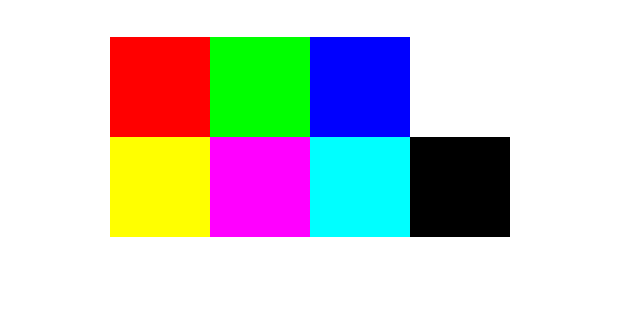

ภาพที่เห็นสามารถถูกแปลงเป็นข้อมูลของ pixel ได้โดยที่เราระบุถึงค่า R G และ B ของแต่ละ pixel 

โดยที่ค่า R G และ B นั้นถูกเสกลให้อยู่ระหว่าง 0 ถึง 1 เราจะได้ข้อมูล RGB ของแต่ละสีโดยเรียงตามลำดับ R G B เป็นดังต่อไปนี้

หากเราสมมุติว่าแต่ละช่องมีขนาด 100 x 100 ตารางpixel  เราสามารถเขียน Tensor ได้ดังต่อไปนี้


$$\begin{array}{l}
\mathbf{O}=\textrm{ones}\left(100\right)\\
\mathbf{Z}=\textrm{zeros}\left(100\right)\\
\mathbf{R}=\left\lbrack \begin{array}{cccc}
\mathbf{O} & \mathbf{Z} & \mathbf{Z} & \mathbf{O}\\
\mathbf{O} & \mathbf{O} & \mathbf{Z} & \mathbf{Z}
\end{array}\right\rbrack \\
\mathbf{G}=\left\lbrack \begin{array}{cccc}
\mathbf{Z} & \mathbf{O} & \mathbf{Z} & \mathbf{O}\\
\mathbf{O} & \mathbf{Z} & \mathbf{O} & \mathbf{Z}
\end{array}\right\rbrack \\
\mathbf{B}=\left\lbrack \begin{array}{cccc}
\mathbf{Z} & \mathbf{Z} & \mathbf{O} & \mathbf{O}\\
\mathbf{Z} & \mathbf{O} & \mathbf{O} & \mathbf{Z}
\end{array}\right\rbrack \\
\mathbf{I}=\textrm{cat}\left(3,\mathbf{R},\mathbf{G},\mathbf{B}\right)
\end{array}$$


แต่แทนที่เราจะเขียนออกมาทีละค่า เราสามารถดึงข้อมูลจากตารางสีและสร้างเมตริกซ์ขึ้นโดยอัตโนมัติซึ่งเขียนเป็นโปรแกรมคร่าวๆได้ดังนี้

cat เป็นฟังก์ชั่นทีทำหน้าที่ซ้อนเมตริกซ์ตามแนวมิติที่ระบุไว้ สำหรับกรณีตัวอย่าง เราได้ทำการซ้อนมิติในมิติที่ 3 เนื่องจากภาพ RGB นั้นต้องใช้ tensor 3 มิติ (กว้าง ยาว และ ค่า RGB)

### 3.4) กระบวนการในการคำนวณเมตริกซ์

ตราบใดที่เราทำตามหลักของการคำนวณเมตริกซ์ เราสามารถใช้ฟังก์ชั่นพื้นฐานใน MATLAB ได้ดังต่อไปนี้

- +,- การบวก,ลบเมตริกซ์ (ขนาดของเมตริกซ์ทั้งสองต้องเท่ากัน)

- * การคูณเมตริกซ์ (จำนวนหลักของเมตริกซ์ด้านหน้าต้องเท่ากับจำนวนแถวของเมตริกซ์ด้านหลัง)

- / การนำเมตริซ์มาผกผันและคูณต่อด้านหลัง (เมตริกซ์ที่อยู่ข้างหลังต้องเป็นเมตริกซ์จัตุรัสเท่านั้น) (matrix right division)

- \ การนำเมตริซ์มาผกผันและคูณต่อด้านหน้า (เมตริกซ์ที่อยู่ข้างหน้าต้องเป็นเมตริกซ์จัตุรัสเท่านั้น) (matrix left division)

- ^ การยกกำลังเมตริกซ์ (ต้องเป็นเมตริกซ์จัตุรัสเท่านั้น)

- ' ทำการ transpose

- inv() ทำการหาเมตริกซ์ผกผัน (ต้องเป็นเมตริกซ์จัตุรัสเท่านั้น)

- det() หา determinant ของเมตริกซ์ (ต้องเป็นเมตริกซ์จัตุรัสเท่านั้น)

- sqrtm(), expm(), logm() (ต้องเป็นเมตริกซ์จัตุรัสเท่านั้น)

ยกตัวอย่างเช่น

### 
$$\begin{array}{l}
\mathbf{A}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack \\
\mathbf{B}=\left\lbrack \begin{array}{cc}
1 & 5\\
2 & 6\\
3 & 7\\
4 & 8
\end{array}\right\rbrack \\
\mathbf{c}=\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack 
\end{array}$$


เราสามารถนำ $\mathbf{A}$ มาคูณกับ $\mathbf{B}$ ได้เนื่องจากขนาดของทั้งสองเมตริกซ์เป็นไปตามหลักของการคูณ

เรายังสามารถประยุกต์ใช้ matrix operationในการแก้สมการเชิงเส้นได้อีกด้วย


$$\begin{array}{l}
2x+y-z=1\\
x+z=2\\
2y+2z=1
\end{array}$$



$$\begin{array}{l}
\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack 
\end{array}$$
  

### 3.5) กระบวนการในการคำนวณทีละสมาชิกเมตริกซ์

เช่นเดียวกับเวกเตอร์ เราสามารถทำการคำนวณกับทีละสมาชิกได้ (Element-wise operation) เช่น


$$y=a^2$$


## โจทย์

### ข้อที่ 1

จากจุดทั้งสามจุดในปริภูมิ 3 มิติที่กำหนดให้ (${\mathbf{p}}_1$,${\mathbf{p}}_2$ และ ${\mathbf{p}}_3$) จงหาเวกเตอร์ที่ตั้งฉากกับระนาบที่ผ่านทั้งสามจุดนี้ และพิสูจน์ว่าเวกเตอร์นั้นตั้งฉากจริงกับระนาบ


$$\begin{array}{l}
{\mathbf{p}}_1 =\left\lbrack \begin{array}{c}
1\\
2\\
3
\end{array}\right\rbrack ,\;{\mathbf{p}}_2 =\left\lbrack \begin{array}{c}
-1\\
0\\
1
\end{array}\right\rbrack ,\;{\mathbf{p}}_3 =\left\lbrack \begin{array}{c}
1\\
0\\
2
\end{array}\right\rbrack \\

\end{array}$$


%p1 = 
%p2 = 
%p3 =

### ข้อที่ 2

กำหนดให้สัญญาณที่มี 2 ช่องที่เปลี่ยนแปลงไปตามเวลา สามารถจำลองได้ดังสมการนี้


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =e^{-\beta t} \left\lbrack \begin{array}{c}
\cos \left(\omega t\right)\\
\sin \left(\omega t\right)
\end{array}\right\rbrack$$


และ เวกเตอร์ของเวลา (Time Vector)


$$\mathbf{t}=\left\lbrack \begin{array}{c}
0\\
\Delta t\\
\vdots \\
\left(N-1\right)\Delta t
\end{array}\right\rbrack$$



$$\begin{array}{l}
\beta =0\ldotp 2,\;\omega =2\pi \;\\
\Delta t=0\ldotp 1,\;\;N=20
\end{array}$$


จงสร้างเมตริกซ์ที่อธิบายสัญญาณโดยกำหนดให้ มิติแรกเป็นเวลา และมิติที่สอง เป็นช่องของสัญญาณ

%beta = 0.2
%omega = 2sym(pi)
%dt = 0.1
%N = 20
%t = 
%Y = 

### ข้อที่ 3

จงแก้หาตัวแปร $y_i$ แต่ละตัว ด้วยเมตริกซ์


$$\begin{array}{l}
x_1 +x_2 +x_3 =1\\
x_2 -x_3 =-1\\
x_1 -x_2 =1
\end{array}$$



$$\begin{array}{l}
y_1 =x_1 -x_3 \\
y_2 =x_2 +x_3 
\end{array}$$
